# Brachistocrone (Bernoulli feladat)

File:   anal3_varszam_1_brachistocrone.m

Author: Polcz Péter (ppolcz@gmail.com)

Created on 2016.09.30. Friday, 12:57:39

Reviewed on 2017. November 07.

## Brachistocrone - Euler Lagrange equations

`Igy lehet kiszamitani az Euler Lagrange egyenleteket (ha esetleg nincs kedve kezzel kiszamitani az embernek)`


% szimbolikus y(x) fuggveny deklaralasa
syms y(x)

% gravitacios gyorsulas
syms g positive

% Igy is lehetne bejelenteni, hogy g pozitiv szam
% assume(g,'positive')

disp 'F(x,y(x),y'(x)) = '

F(x,y(x),y(x)) = 


F = sqrt((1+diff(y)^2)/(2*g*y))

$$F(x) = \frac{\sqrt{\frac{{\left(\frac{\partial }{\partial x}y\left(x\right)\right)}^{2}+1}{2\,y\left(x\right)}}}{\sqrt{g}}$$

Kiszamitjuk az F-hez tartozo Euler-Lagrange egyenletek: [Ez meg nagyon csunya lesz]

ELeq = functionalDerivative(F,y) == 0

$$ELeq(x) = -\frac{2\,y\left(x\right)\,\frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+{\left(\frac{\partial }{\partial x}y\left(x\right)\right)}^{2}+1}{8\,\sqrt{g}\,{y\left(x\right)}^{3}\,{\left(\frac{1}{2\,y\left(x\right)}+\frac{{\left(\frac{\partial }{\partial x}y\left(x\right)\right)}^{2}}{2\,y\left(x\right)}\right)}^{3/2}}=0$$

Euler-Lagrange egyenletek egyszerűsített alakja

ELeq = simplify(ELeq)

$$ELeq(x) = 2\,y\left(x\right)\,\frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+{\left(\frac{\partial }{\partial x}y\left(x\right)\right)}^{2}=-1$$

## Brachistochrone - szelsoertekfeltetelek numerikus kiszamitasa

EGYSZERU ESET: ha a v0 kezdeti sebesseg 0

Az integral kiszamitasat ez a script NEM tartalmazza, csak a mar altalanos alakban adott megoldas ismeretlen egyutthatoit szamolom ki. A problema reszletes levezetese megtalalhato a lenti scannelt jegyzetben. [Brachistochrone_variacioszamitas_levezetes.pdf](http://users.itk.ppke.hu/~polpe/files/targyak/anal3/Brachistochrone_variacioszamitas_levezetes.pdf)

figure, hold on, axis equal tight

% kezdeti feltetelek
x0 = 0;
y0 = 1;
x1 = 5;
y1 = 0;

% a mar kezzel kiszamolt egyutthatok
theta1 = 0;

% kb minden egyutthatot ki tudtunk szamolni kezzel (lasd kidolgozott
% jegyzet), csak a theta2 parameter hianyzik
obj = @(theta2) theta2 - sin(theta2) - x1 / (y0 - y1) * (1 - cos(theta2));

theta2 = fsolve(obj, pi);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



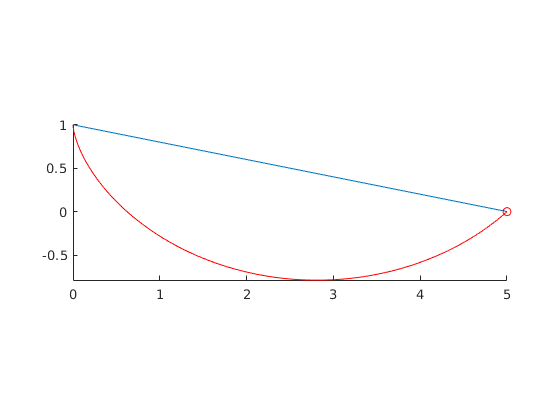

k = 2*x1 / (theta2 - sin(theta2));

theta = linspace(theta1,theta2,100);
x = k/2 * (theta - sin(theta));
y = y0 - k/2 * (1 - cos(theta));

plot([x0 x1], [y0 y1])
plot(x,y, 'r', x(end), y(end), 'ro')

## Brachistochrone - szelsoertekfeltetelek numerikus kiszamitasa

BONYOLULTABB ESET: kulonbozo kezdeti sebessegek mellett

figure, hold on, axis equal tight

g = 10; % gravitacios gyorsulas
m = 2;  % tomegpont tomege

% kezdeti feltetelek
x0 = 0;
y0 = 1;
x1 = 5;
y1 = 0;

% ismeretlen egyutthatok
syms k b theta1 theta2 

% a kezdeti sebesseget egyelore parameterkent kezelem
syms v0

% Kezdeti energia (belekalkulalva, hogy kezdeti sebessege is lehet)
E0 = m*v0^2/2 + m*g*y0;

% Objektiv fuggveny, ezt kell nullazunk, ez tartalmazza a kezdeti
% felteteleket nullara rendezve
obj_sym = [
    E0/(m*g) - k/2 * (1 - cos(theta1)) - y0 % y(theta1) - y0 = 0
    b + k/2 * (theta1 - sin(theta1)) - x0   % x(theta1) - x0 = 0
    E0/(m*g) - k/2 * (1 - cos(theta2)) - y1 % y(theta2) - y0 = 0
    b + k/2 * (theta2 - sin(theta2)) - x1   % x(theta2) - x0 = 0
    ];

obj = @(v0_var) matlabFunction(subs(obj_sym,v0,v0_var), 'vars', {[k ; b ; theta1 ; theta2]});

for v0_num = 1:2:8
    
    % Az fsolve-nak meg kell adni egy kezdeti pontot, ahonnan iteral,
    % egyaltalan nem biztos, hogy jo megoldast fog megtalalni, az sem
    % biztos, hogy ez a legertelmesebb kezdeti pont.
    sol = fsolve(obj(v0_num), [x1-x0 ; 0 ; 0 ; pi]);
    
    % Ez mar a megoldas!
    k = sol(1);
    b = sol(2);
    theta1 = sol(3);
    theta2 = sol(4);
    
    % Ez mar csak kirajzolas
    plot([x0 x1], [y0 y1])
    theta = linspace(theta1,theta2,100);
    x = b + k/2 * (theta - sin(theta));
    y = subs(E0,v0,v0_num)/(m*g) - k/2 * (1 - cos(theta));
    plot(x,y, 'r', x(end), y(end), 'ro')
    
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

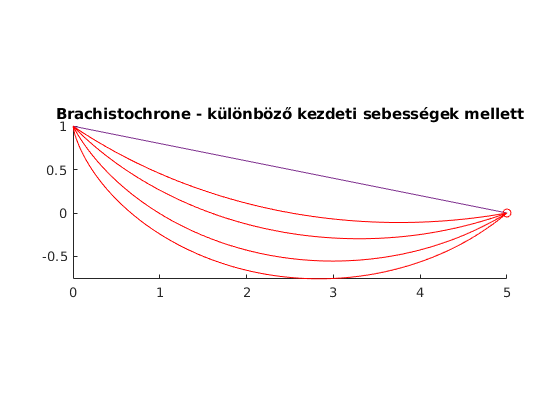

title 'Brachistochrone - különböző kezdeti sebességek mellett'

## Euler Lagrange egyenletek kiszamitasa alapmuveletekkel

Ez nagyon el van bonyolitva, felejtsuk el!!

y0_num = 1;
C_num = 1;

L = @(F) diff(F,y)

L = function_handle with value:
    @(F)diff(F,y)


syms x u v q0 C real
y = sym('y(x)', 'real');

dq = diff(y);

F = sqrt(1 + v^2) / sqrt(u - q0);

F_q = subs(F, [u,v], [y,dq])

$$F\_q = \frac{\sqrt{{\left(\frac{\partial }{\partial x}y\left(x\right)\right)}^{2}+1}}{\sqrt{y\left(x\right)-q_{0}}}$$

Euler egyenlet:

Euler_eq_q = simplify( subs(diff(F,u), [u,v], [y,dq]) - diff( subs(diff(F,v), [u,v], [y,dq]) ) )

$$Euler\_eq\_q = -\frac{{\left(\frac{\partial }{\partial x}y\left(x\right)\right)}^{2}-2\,q_{0}\,\frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+2\,y\left(x\right)\,\frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+1}{2\,{\left(y\left(x\right)-q_{0}\right)}^{3/2}\,{\left({\left(\frac{\partial }{\partial x}y\left(x\right)\right)}^{2}+1\right)}^{3/2}}$$

Alternatíva:

Euler_alt_q = simplify( F_q - dq * subs(diff(F,v), [u,v], [y,dq]) )

$$Euler\_alt\_q = \frac{1}{\sqrt{y\left(x\right)-q_{0}}\,\sqrt{{\left(\frac{\partial }{\partial x}y\left(x\right)\right)}^{2}+1}}$$


Euler_alt = subs(Euler_alt_q, [y,dq], [u,v]);

assume([q0 >= u , in(q0, 'real'), in(u, 'real')])
sol = solve(Euler_alt-1/C, v);

% Nincs implicit megoldasa
% dsolve(Euler_alt == C)